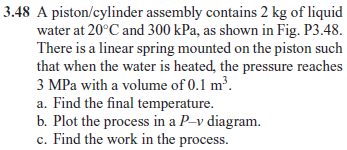

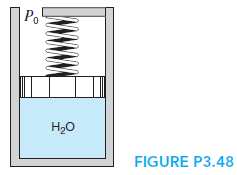

# class

u = symunit;

# state 1 (saturated liquid water)

% --------------------
% given
m1 = 2*u.kg;
p1 = 300*u.kPa;
T1 = 20*u.Celsius;
% --------------------
% specific volume
v1 = 0.001002*u.m^3/u.kg;
% --------------------
% specific internal energy
u1 = 83.94*u.kJ/u.kg;
% --------------------
% volume
Vol1 = m1*v1;
% --------------------

# state 2 (liquid-vapor water mix)

% --------------------
% given
m2 = m1;
p2 = 3*u.MPa;
Vol2 = 0.1*u.m^3;
v2 = Vol2/m2;
% --------------------
% temperature
T2 = 233.90*u.Celsius;
% quality
vf2 = 0.001216*u.m^3/u.kg;
vfg2 = 0.06546*u.m^3/u.kg;
x2 = (v2-vf2)/vfg2;
% --------------------
% specific internal energy
uf2 = 1004.76*u.kJ/u.kg;
ufg2 = 1599.34*u.kJ/u.kg;
u2 = uf2+x2*ufg2;
% --------------------

# work done

W_12 = rewrite((p1+p2)*(Vol2-Vol1)/2, u.kJ);
W_12_vpa = vpa(W_12, 5) %#ok

$$W\_12\_vpa = 161.69\,\mathrm{kJ}$$

clear W_12_vpa;

# heat transfer

Q_12 = m2*u2-m1*u1+W_12;
Q_12_vpa = vpa(Q_12, 6) %#ok

$$Q\_12\_vpa = 4387.15\,\mathrm{kJ}$$

clear Q_12_vpa;